This script uses analytical theory to fit experimental SAXS data of Polyimide-PEG random copolymers.

Load experiment data.

clear;
close all
addpath('functions/')
data = load('exp-data/PEG30undoped.csv');  % SAXS data with q in A^(-1)
                                           % 30wt ~= 16mol%

TV = [22,40:20:180];  % temperature in degree C
TK = TV+273.15;       % temperature in Kelvin
q = data(:,1);
s = data(:,2:end);

Define a small q cutoff and estimate peak intensity S(q~=0).

% if PEG wt% = 0.30
qmin0 = 0.03803;
qminf = 0.04094;

iqmin0 = find(q==qmin0);
iqminf = find(q==qminf);
smin = mean(s(iqmin0:iqminf,:));
sminstd = std(1./s(iqmin0:iqminf,:));

Make a plot of structure factor.

%rm = 32.05; % estimate end-to-end distance of a "chemical monomer" in unit Angstrom
rm=1;
figure;hold

Current plot held


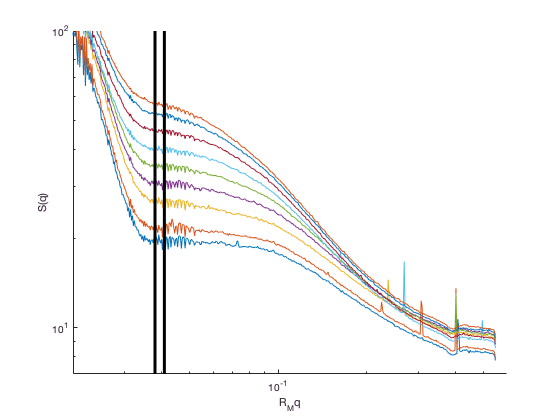

% at which temperature?
Trange=1:9;

for T=Trange
    plot(q*rm,s(:,T));
end
plot([qmin0,qmin0]*rm,[7,1e2],'k-','linewidth',3)
plot([qminf,qminf]*rm,[7,1e2],'k-','linewidth',3)

xlabel('R_Mq');ylabel('S(q)')
set(gca,'xscale','log');set(gca,'yscale','log');
xlim([0.02,0.6]*rm);ylim([7,1e2]);

 Next plot temperature versus estimated inverse peak intensity. Theoretical estimate of ODT temperature is the x-intercept of the plot.

figure;hold;

Current plot held


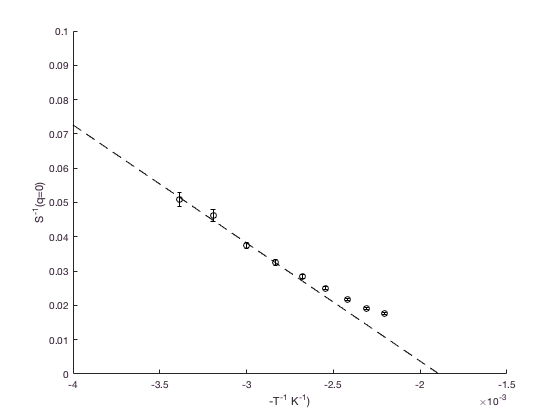

xp = -1./TK; %negative sign to account for temperature effects on SAXS intensity (degree of phase segregation)
yp = power(smin,-1);
errorbar(xp,yp,sminstd,'ko')
xlabel('-T^{-1} K^{-1})');ylabel('S^{-1}(q=0)')

% fit linear regression at q*=0
xfit = 1:3;  % linear fit regime at low Temperature
x = xp(xfit)';
X = [ones(length(x),1) x];
y = yp(xfit)';
b = X\y;
xp = linspace(-4,-1,100)*1e-3;
yp = b(2)*xp+b(1);
plot(xp,yp,'k--');
ylim([0,.1])

Plot analytical structure factor.

% polymer parameters
N=100;  % total of 100 monomers
NM=0.1; % each monomer has 0.1 Kuhn steps
LAM=0.00; % ideal random copolymer
FA=0.165;    % equal chemical composition

% length parameters
RM=sqrt(r2wlc(NM));  % end-to-end distance of a monomers
K0=1e-1;  % minimum wavevector
KF=1e2;   % maximum wavevector
NK=101;  % number of wavevectors
K=transpose(logspace(log10(K0),log10(KF),NK))/RM;

% evaluate s2inv
[SINV]=s2invwlc(N,NM,FA,LAM,K);
[KS,SS]=kmaxwlc(N,NM,FA,LAM);
CHIS=0.5*SS*NM;

CHIV=linspace(0.1,0.9,9);   % Flory-Huggins parameter in units of CHIS (ODT CHI)
figure;hold

Current plot held


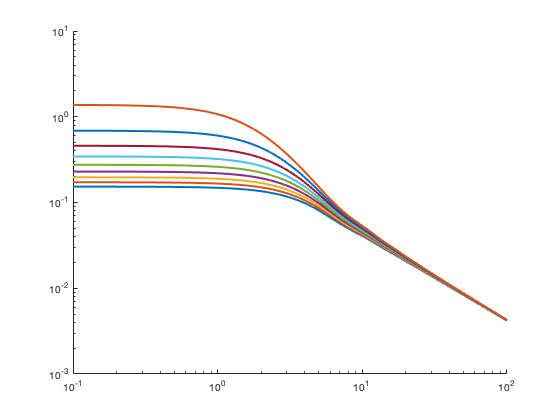

for CHI=CHIV
    plot(RM*K,1./(-2*CHI*CHIS+SINV*NM),'-','LineWidth',2)
end
set(gca,'xscale','log');set(gca,'yscale','log');

Plot theoretical prediction of temperature versus estimated inverse peak intensity.

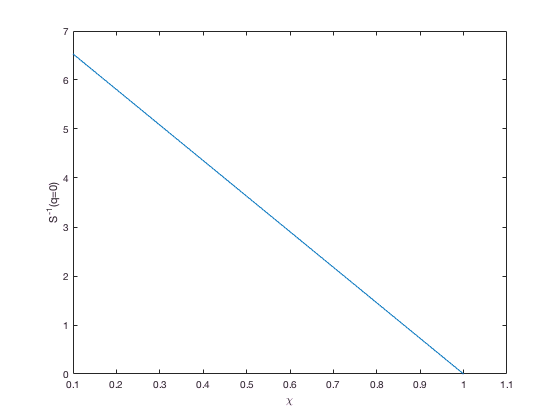

CHIV=linspace(0.1,1.1,9);   % Flory-Huggins parameter in units of CHIS (ODT CHI)
Smin = power(-2*CHIV*CHIS+1/(FA*(1-FA)),-1);  % zero q analytical structure factor
figure;plot(CHIV,1./Smin);ylim([0,7])
xlabel('\chi');ylabel('S^{-1}(q=0)')

Start fitting analytical S(q) to experimental data.

% choose fitting range
IT = 9;  % at which temperature
qf = q(iqmin0:end);
sf = s(iqmin0:end,IT);

% fit to structure factor
x0 = [0.8,32,500];  %initial fit guess, % x(1) = CHI, x(2) = intensity scale, x(3) = Rm
[x,sfit]=saxsfit(qf,sf,x0,N,NM,FA,LAM,CHIS);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the selected value of the function tolerance.

<stopping criteria details>




figure;hold;

Current plot held


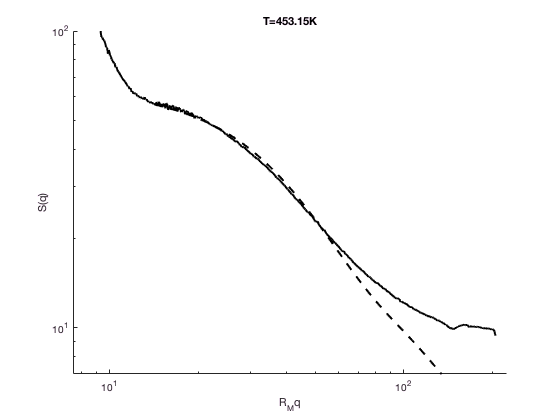

plot(q*x(3),s(:,IT),'k-','LineWidth',2) % experiment data
plot(qf*x(3),sfit,'k--','LineWidth',2) % theoretical fit
xlabel('R_Mq');ylabel('S(q)');title(strcat('T=',num2str(TK(IT)),'K'))
set(gca,'xscale','log');set(gca,'yscale','log');
xlim([0.02,0.6]*x(3));ylim([7,1e2]);


% output fitted result
chifit = x(1)

chifit = 0.5701

intensityfit = x(2)

intensityfit = 198.9151

rmfit = x(3)

rmfit = 374.5899

Start fitting analytical S(q) to experimental data.

% choose fitting range
IT = 1;  % at which temperature
qf = q(iqmin0:end);
sf = s(iqmin0:end,IT);

% fit to structure factor
x0 = [0.8,32,500];  %initial fit guess, % x(1) = CHI, x(2) = intensity scale, x(3) = Rm
[x,sfit]=saxsfit(qf,sf,x0,N,NM,FA,LAM,CHIS);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the selected value of the function tolerance.

<stopping criteria details>




figure;hold;

Current plot held


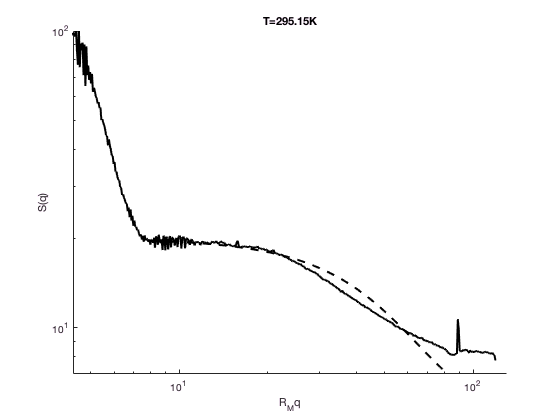

plot(q*x(3),s(:,IT),'k-','LineWidth',2) % experiment data
plot(qf*x(3),sfit,'k--','LineWidth',2) % theoretical fit
xlabel('R_Mq');ylabel('S(q)');title(strcat('T=',num2str(TK(IT)),'K'))
set(gca,'xscale','log');set(gca,'yscale','log');
xlim([0.02,0.6]*x(3));ylim([7,1e2]);


% output fitted result
chifit = x(1)

chifit = 0.0099

intensityfit = x(2)

intensityfit = 143.8532

rmfit = x(3)

rmfit = 217.3273